clc; clear all; close all;
syms s C1 C2 C3 G ;

%Transfer function of the plant G
num = [7.4,14,6.7];
den = [1,2.6,10,17,8];
G = tf(num,den)

G =
 
        7.4 s^2 + 14 s + 6.7
  ---------------------------------
  s^4 + 2.6 s^3 + 10 s^2 + 17 s + 8
 
Continuous-time transfer function.
Model Properties



%Transfer function of the plant G
num = [0.57,4.1];
den = [0.23,1];
C1 = tf(num,den)

C1 =
 
  0.57 s + 4.1
  ------------
   0.23 s + 1
 
Continuous-time transfer function.
Model Properties



num = [0.57,2.4];
den = [0.13,1];
C2 = tf(num,den)

C2 =
 
  0.57 s + 2.4
  ------------
   0.13 s + 1
 
Continuous-time transfer function.
Model Properties



num = [0.57,1.6];
den = [0.091,1];
C3 = tf(num,den)

C3 =
 
  0.57 s + 1.6
  ------------
  0.091 s + 1
 
Continuous-time transfer function.
Model Properties


## Question a)

Plot, in one figure, the Nyquist contours for the three open-loop systems Li(s)—with i = 1,2,3. Utilize the nyquist function in Matlab for this purpose, consider the interval [−2,0.2] for the x-axis, the interval [−1,1] for the y-axis and include a legend. 

%Defines the open loop system
L1 = C1 *G

L1 =
 
          4.218 s^3 + 38.32 s^2 + 61.22 s + 27.47
  --------------------------------------------------------
  0.23 s^5 + 1.598 s^4 + 4.9 s^3 + 13.91 s^2 + 18.84 s + 8
 
Continuous-time transfer function.
Model Properties


L2 = C2 *G

L2 =
 
          4.218 s^3 + 25.74 s^2 + 37.42 s + 16.08
  --------------------------------------------------------
  0.13 s^5 + 1.338 s^4 + 3.9 s^3 + 12.21 s^2 + 18.04 s + 8
 
Continuous-time transfer function.
Model Properties


L3 = C3 *G

L3 =
 
           4.218 s^3 + 19.82 s^2 + 26.22 s + 10.72
  ----------------------------------------------------------
  0.091 s^5 + 1.237 s^4 + 3.51 s^3 + 11.55 s^2 + 17.73 s + 8
 
Continuous-time transfer function.
Model Properties


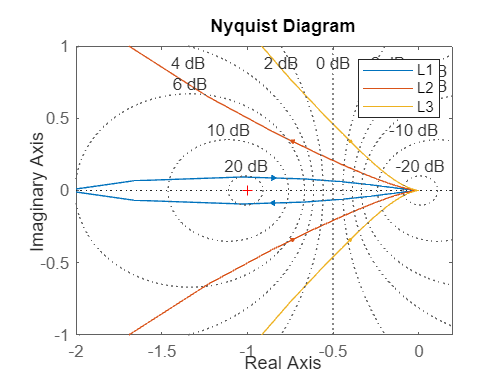


%Plots the plots
figure;
nyquist(L1,L2,L3)
xlim([-2, 0.2]);
ylim([-1, 1]);
legend;
grid on;

## Question b)

Use the Nyquist contours from question a) to determine, for each controller, whether the closed-loop interconnection in Figure 7 is stable. Please explain briefly how you came to this conclusion.

## Question c)

For each open-loop system Li(s)—with i = 1,2,3—determine the crossover frequency ωc in rad s , the phase margin PM in degrees, the gain margin GM in dB and the modulus margin MM in dB. You may round off your answer to one decimal place. If there are multiple frequencies satisfying |L(jω)| = 1 or ∠L(jω) = −180◦—that is, if there are multiple frequencies at which these margins could be calculated—please consider the one that is most critical in terms of stability. Note that: the margin command in Matlab will also consider this most critical frequency when calculating the PM and GM.

% Initialize results storage
systems = {'L1', 'L2', 'L3'};
open_loops = {L1, L2, L3};

% Print header
fprintf('System    wc (rad/s)    PM (°)    GM (dB)    MM (dB)\n');

System    wc (rad/s)    PM (°)    GM (dB)    MM (dB)


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------



% Loop through each system and calculate margins
for i = 1:length(systems)
    try
        % Check for system stability
        poles = pole(open_loops{i});
        if any(real(poles) >= 0)
            error('System is unstable (poles in the right half-plane).');
        end
        
        % Calculate gain margin (GM), phase margin (PM), and crossover frequencies
        [GM, PM, Wcg, Wcp] = margin(open_loops{i});

        % Calculate Modulus Margin (MM)
        MM = -20 * log10(abs(evalfr(open_loops{i}, 1))); % MM = -20*log10(|L(j1)|)

        % Handle undefined margins
        if isempty(GM) || isempty(PM) || isempty(Wcp)
            GM_dB = NaN;
            PM_deg = NaN;
            Wcp_rad = NaN;
        else
            GM_dB = 20 * log10(GM); % Convert GM to dB
            PM_deg = PM; % Phase margin in degrees
            Wcp_rad = Wcp; % Crossover frequency in rad/s
        end

        % Print results
        fprintf('%-8s %10.1f %10.1f %10.1f %10.1f\n', systems{i}, Wcp_rad, PM_deg, GM_dB, MM);

    catch ME
        % Handle unstable or problematic systems
        fprintf('%-8s     UNSTABLE SYSTEM\n', systems{i});
        warning('Error analyzing system %s: %s', systems{i}, ME.message);
    end
end

L1              5.6       -5.3       -6.9       -8.8
L2              5.6       25.9        Inf       -5.6
L3              5.6       45.3        Inf       -3.2


## Question d)

Determine the step response of the closed-loop system for each controllerCi(s) with i = 1,2,3. Add all plots on the same figure and plot over a duration of 7.6 seconds.

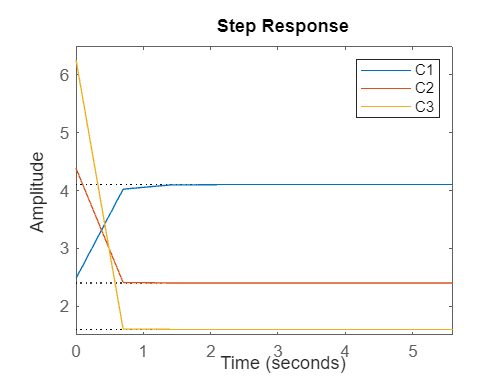

time = 0:0.7:6; % Sets the time interval
step(C1,time)
hold on
step(C2,time)
hold on
step(C3,time)
legend
hold off

## Question e)

For the closed-loop response of each controller in question d, describe how well it is able to track the step reference signal. Compare each controller with respect to the following criteria: overshoot, steady state error, and settling time? Please explain, per criterium, which controller you would choose.

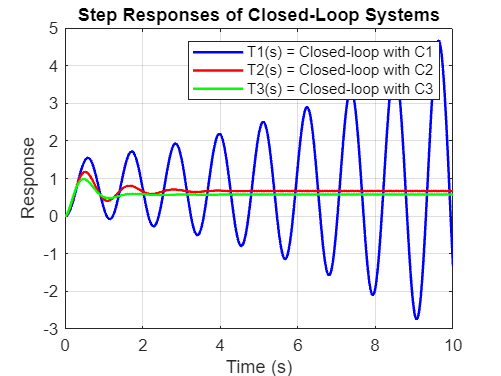


T1 = feedback(C1 * G, 1);  % Closed-loop system with C1
T2 = feedback(C2 * G, 1);  % Closed-loop system with C2
T3 = feedback(C3 * G, 1);  % Closed-loop system with C3

% Time vector for simulation
t = 0:0.01:10;

% Step responses
[y1, t1] = step(T1, t);  % Response for T1
[y2, t2] = step(T2, t);  % Response for T2
[y3, t3] = step(T3, t);  % Response for T3

% Plot step responses
figure;
plot(t1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(t2, y2, 'r', 'LineWidth', 1.5);
plot(t3, y3, 'g', 'LineWidth', 1.5);
grid on;
legend('T1(s) = Closed-loop with C1', 'T2(s) = Closed-loop with C2', 'T3(s) = Closed-loop with C3');
title('Step Responses of Closed-Loop Systems');
xlabel('Time (s)');
ylabel('Response');


% Analyze step response characteristics
info1 = stepinfo(T1);

info2 = stepinfo(T2);
info3 = stepinfo(T3);

% Compute steady-state error (final value)
final_value1 = y1(end);
final_value2 = y2(end);
final_value3 = y3(end);
steady_state_error1 = abs(1 - final_value1);
steady_state_error2 = abs(1 - final_value2);
steady_state_error3 = abs(1 - final_value3);

% Display results
fprintf('Controller Comparison:\n');

Controller Comparison:


fprintf('Criterion                T1 (C1)    T2 (C2)    T3 (C3)\n');

Criterion                T1 (C1)    T2 (C2)    T3 (C3)


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------


fprintf('Overshoot (%%)          %8.2f   %8.2f   %8.2f\n', info1.Overshoot, info2.Overshoot, info3.Overshoot);

Overshoot (%)               NaN      75.91      71.58


fprintf('Settling Time (s)       %8.2f   %8.2f   %8.2f\n', info1.SettlingTime, info2.SettlingTime, info3.SettlingTime);

Settling Time (s)            NaN       3.55       1.98


fprintf('Steady-State Error      %8.4f   %8.4f   %8.4f\n', steady_state_error1, steady_state_error2, steady_state_error3);

Steady-State Error        2.3278     0.3322     0.4274
